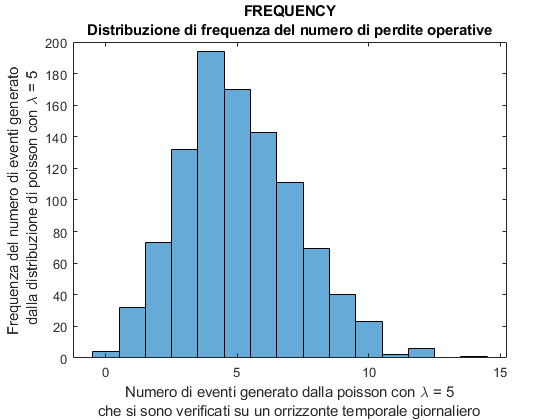

%% PROGETTO Descrivere l’approccio attuariale alla misurazione del rischio operativo
clc
clear
%PARAMETRI A DISCREZIONE DELL'UTENTE
mu=[1.5 1.5 3];
var=[1 2 1];
sigma=sqrt(var);
lambda=5;
n=1000;
alpha=0.99;

k = poissrnd(lambda,n,1);
%distribuzione di poisson utile perchè:
%1)si possono aggregare più distribuzioni di poisson legati al rischio 
%operativo dei tipo di eventi delle business line (ipotesi di indipendenza
%degli eventi nel tempo) PROPRIETA' ADDITIVA
%2)semplice da implementare, basta conoscere il numero medio di volte che
%l'evento si verifica in un arco di tempo (lambda)

k_sort=sort(k);
%le variabili x hanno distribuzione log normale
s=1;
max=max(k);
x=zeros(max,max);
for p=1:3
    for i=1:n
        x(1:k(i),s)=lognrnd(mu(p),sigma(p),k(i),1);
        s=s+1;     
        if s==n+1
            s=1;
            break
        end
    end
    L(p,:)=sum(x); 
    L_sort(p,:)=sort(L(p,:));
    L_var(p)=quantile(L_sort(p,:),alpha);
end
L_mean=mean(L');
C_ar=L_var-L_mean;

figure
histogram(k_sort);
title({'FREQUENCY','Distribuzione di frequenza del numero di perdite operative'});
ylabel({'Frequenza del numero di eventi generato',[' dalla distribuzione di poisson con \lambda = ' num2str(lambda)]});
xlabel({['Numero di eventi generato dalla poisson con \lambda = ' num2str(lambda)],'che si sono verificati su un orrizzonte temporale giornaliero'});

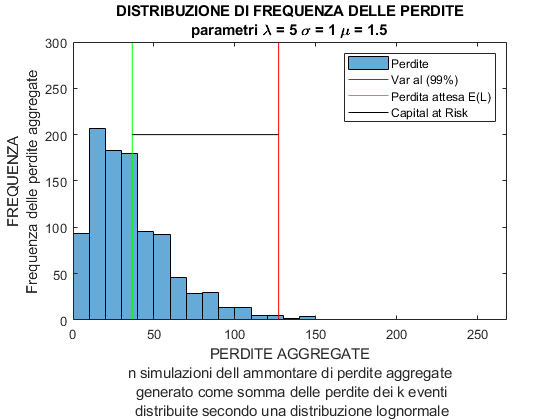


% figure
% subplot(3,1,1);
histogram(L_sort(1,:));
title({'DISTRIBUZIONE DI FREQUENZA DELLE PERDITE',['parametri \lambda = ' num2str(lambda) ' \sigma = ' num2str(sigma(1)) ' \mu = ' num2str(mu(1))]});
hold on
plot([L_var(1),L_var(1)],[0 300],'r');
plot([L_mean(1),L_mean(1)],[0 300],'g');
plot([L_mean(1),L_var(1)],[200 200],'k');
legend('Perdite','Var al (99%)','Perdita attesa E(L)','Capital at Risk');
axis([0 L_sort(1,end) 0 300])
ylabel({'FREQUENZA','Frequenza delle perdite aggregate'});
xlabel({'PERDITE AGGREGATE','n simulazioni dell ammontare di perdite aggregate',' generato come somma delle perdite dei k eventi',' distribuite secondo una distribuzione lognormale'});
hold off

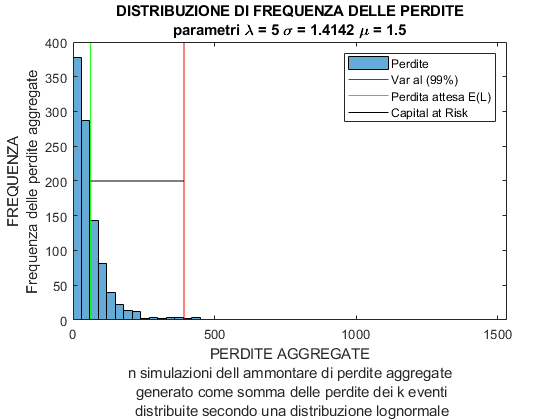


% subplot(3,1,2);
histogram(L_sort(2,:));
title({'DISTRIBUZIONE DI FREQUENZA DELLE PERDITE',['parametri \lambda = ' num2str(lambda) ' \sigma = ' num2str(sigma(2)) ' \mu = ' num2str(mu(2))]});
hold on
plot([L_var(2),L_var(2)],[0 400],'r');
plot([L_mean(2),L_mean(2)],[0 400],'g');
plot([L_mean(2),L_var(2)],[200 200],'k');
legend('Perdite','Var al (99%)','Perdita attesa E(L)','Capital at Risk');
axis([0 L_sort(2,end) 0 400])
ylabel({'FREQUENZA','Frequenza delle perdite aggregate'});
xlabel({'PERDITE AGGREGATE','n simulazioni dell ammontare di perdite aggregate',' generato come somma delle perdite dei k eventi',' distribuite secondo una distribuzione lognormale'});
hold off

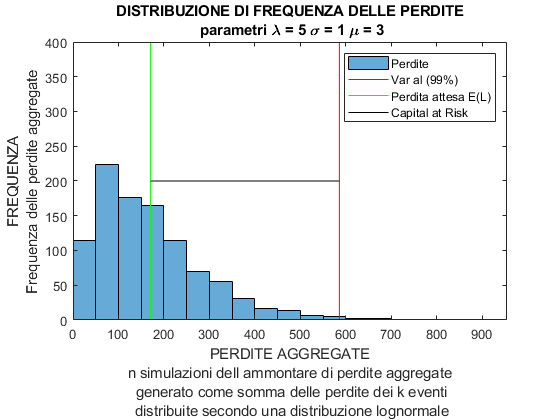


% subplot(3,1,3);
histogram(L_sort(3,:));
title({'DISTRIBUZIONE DI FREQUENZA DELLE PERDITE',[' parametri \lambda = ' num2str(lambda) ' \sigma = ' num2str(sigma(3)) ' \mu = ' num2str(mu(3))]});
hold on
plot([L_var(3),L_var(3)],[0 400],'r');
plot([L_mean(3),L_mean(3)],[0 400],'g');
plot([L_mean(3),L_var(3)],[200 200],'k');
legend('Perdite','Var al (99%)','Perdita attesa E(L)','Capital at Risk');
axis([0 L_sort(3,end) 0 400])
ylabel({'FREQUENZA','Frequenza delle perdite aggregate'});
xlabel({'PERDITE AGGREGATE','n simulazioni dell ammontare di perdite aggregate',' generato come somma delle perdite dei k eventi',' distribuite secondo una distribuzione lognormale'});
hold off